**HEAD IMAGING - BACKGROUND FIELD**

This script computes the background (incident) electric field for a realistic 2-D head model. The permittivity distribution is derived from a segmented MRI slice using the 4-Cole-Cole dielectric model (Gabriel et al. 1996) and mapped onto a pre-built finite-element mesh.

The mesh is loaded from a .mat file that was prepared in advance from the patient anatomy. This script is organized as follows:

- Load MRI tissue labels and compute the complex permittivity map

- Load the pre-built FEM mesh and probe node indices

- Map the pixel-level permittivity map onto the mesh cells

- Solve the total E-field

- Save the background field and mesh geometry

clc;
close all;
clear;
addpath('../../Forward_solvers/lib');
addpath('lib');

**OPERATING FREQUENCY AND BACKGROUND MEDIUM**

The simulation frequency must match across all three pipeline steps. The scalar background_epsc is the complex relative permittivity of the coupling medium surrounding the head (not the tissue inside the DOI).

sim.f            = 1e9;
sim.omega           = 2*pi*sim.f ;

**LOAD MRI LABELS**

The MRI slice is stored as a grayscale image encoded in the range [0, 255]. The pixel values are linearly mapped to integer tissue labels [0, 11] that identify 12 distinct tissue classes (0=Background, 1=CSF, 2=Gray Matter, 3=White Matter, 4=Fat, 5=Muscle, 6=Muscle/Skin, 7=Skull, 8=vessels, 9=around fat, 10 =dura matter, 11=bone marrow)

The image resolution is the physical size of each pixel in meters. It is used later by map_permittivity_to_mesh to align the pixel grid with the mesh coordinate system.

label_data = load("MRI_labels/p01.mat");
labels     = round(double(label_data.patient.slice) * 11 / 255);
resolution = 0.5e-3;

**COMPUTE DIELECTRIC MAPS - 4-COLE-COLE MODEL**

The function compute_dielectric_maps assigns a complex relative permittivity value to each pixel based on its tissue label, using the 4-Cole-Cole model:

-   eps*(omega) = eps_inf + sum_n { Delta_n / [1 + (j*omega*tau_n)^(1-alpha_n)] } - j*sigma/(omega*eps0)

Parameters for each tissue class come from Gabriel et al. (1996). The output eps_map is a 2-D complex array of the same size as labels. The permute call reorders the axes to match the coordinate convention of the FEM mesh (column-major to row-major).

materials.background_epsc = 20 - 1i*1;
perm_matrix = compute_dielectric_maps(labels, sim.f);


Frequency: 1000.0000 MHz
Tissue                 eps'       eps''  sigma_eff (S/m)
---------------------------------------------------------
Background           1.0000      0.0000       -0.000000
CSF                 68.4385    -44.1324        2.455199
Gray Matter         52.2823    -17.7132        0.985428
White Matter        38.5773    -11.1790        0.621916
Fat                  5.4470     -0.9617        0.053503
Muscle              54.8111    -17.5833        0.978203
Muscle/Skin         45.7110    -15.8437        0.881425
Skull               12.3633     -2.7980        0.155660
Vessels             61.0650    -28.4535        1.582938
Around Fat          11.2943     -2.0920        0.116382
Dura Mater          44.2008    -17.8549        0.993314
Bone Marrow          5.4854     -0.7784        0.043304



**LOAD PRE-BUILT FEM MESH**

The FEM mesh was generated externally from the patient anatomy and saved as a .mat file. The key fields are:

-   verts           :    (N x 3) vertex coordinates [m] - includes a z column set to zero

-   cells           :    (M x 3) triangle connectivity (1-based node indices)

-   idx_cells_DoI   :    global indices of cells inside the Domain of Interest

-   Ind_probes      :    node indices of the antenna probe positions

mesh_data     = load("Mesh/mesh_p01.mat");
verts         = mesh_data.verts;
verts(:,3)    = [];
cells         = mesh_data.cells;
idx_cells_DoI = mesh_data.idx_cells_DoI;
probeNodes    = mesh_data.Ind_probes;

**MAP PERMITTIVITY TO MESH CELLS**

Each triangular cell centroid is located in the pixel grid of eps_map by nearest-neighbour look-up. Cells outside the DOI are assigned the scalar background_epsc.

perm = map_permittivity_to_mesh( ...
    perm_matrix.complex, verts, cells, resolution, idx_cells_DoI, materials.background_epsc);

**PERMITTIVITY VISUALIZATION**

The mapped permittivity is visualized as a cell-wise patch plot over the triangular mesh.

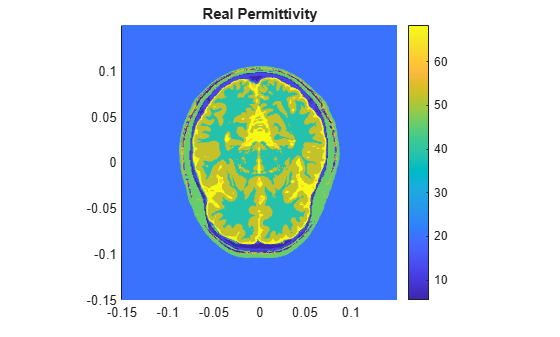

scenario.mesh.Nodes = verts';
scenario.mesh.Elements = cells';
scenario.cellsDOI = idx_cells_DoI;

plotPermittivity(...
    scenario.mesh,...
    perm.real,...
    'Real Permittivity');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

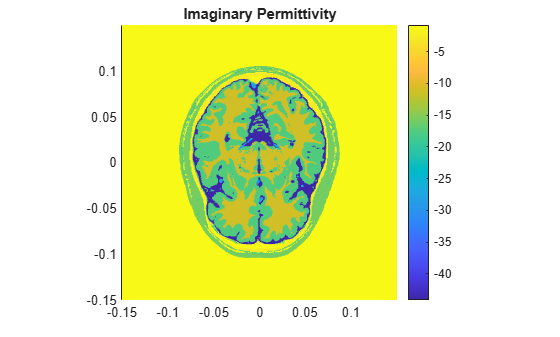


plotPermittivity(...
    scenario.mesh,...
    perm.imag,...
    'Imaginary Permittivity');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

**FEM SOLUTION - BACKGROUND FIELD**

The 2-D Helmholtz equation is solved for all transmitters simultaneously. fem2d returns:

-   Everts    :    vertex-wise complex electric field (nNodes x nAnt)

-   Ecells    :    cell-centroid field (nCells x nAnt), used to build the data operator in imaging

-   Area      :    element areas [m^2], used as quadrature weights

The mesh coordinates passed to fem2d must be 2-D (x, y only). The z column is discarded before the call.

verts_2d = verts(:, 1:2);
current = 1e-3;
[Everts, Ecells, Area] = fem2d( ...
    scenario.mesh.Nodes',...
    scenario.mesh.Elements',...
    perm.complex, ...
    sim.f, ...
    probeNodes, ...
    materials.background_epsc, ...
    [], current);

**FIELD VISUALIZATION**

The field magnitude generated by one selected transmitter is plotted over the head mesh.

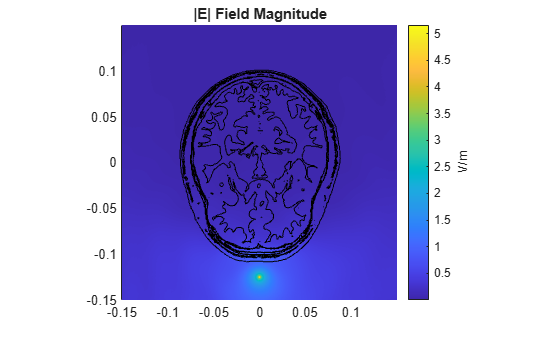

selectedAntenna = 1;
boundaries_struct = load("MRI_labels/boundaries.mat");
boundaries = boundaries_struct.boundaries;
fieldData = Ecells(:,selectedAntenna);

plotField_head(...
    scenario,...
    abs(fieldData),...
    boundaries,...
    '|E| Field Magnitude', 'V/m');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

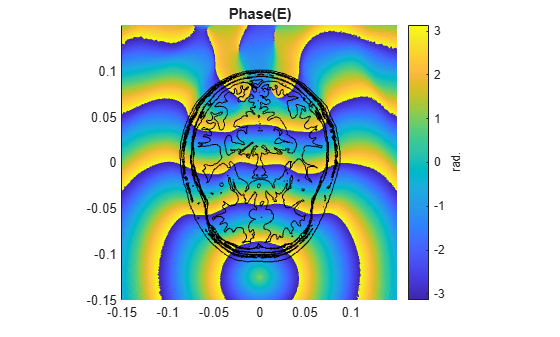

plotField_head(...
    scenario,...
    angle(fieldData),...
    boundaries,...
    'Phase(E)','rad.');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

**SAVE RESULTS**

Two files are saved:

-   background_fields_head.mat    :    Ecells and Everts for all transmitters, perm_cells, current, freq

-   geometry_head.mat               :    2-D mesh topology, probe indices, DOI cell indices, cell areas

nameGEO = 'results/geometry';
nameBF  = 'results/background_fields';

freq = sim.f;

save([nameBF,'.mat'],...
    'Ecells',...
    'Everts',...
    'perm',...
    'current',...
    'freq');

% Geometry Data Export

verts = scenario.mesh.Nodes';
cells = scenario.mesh.Elements';

Ind_probes   = probeNodes;
Ind_cells_doi = scenario.cellsDOI;

save([nameGEO,'.mat'],...
    'verts',...
    'cells',...
    'Ind_probes',...
    'Ind_cells_doi',...
    'Area');
